# Practica Global

## Michal Chrobot, Luke Voss, Finn-Henri Smidt

sumCostes_Annealing = 5.9953e+03

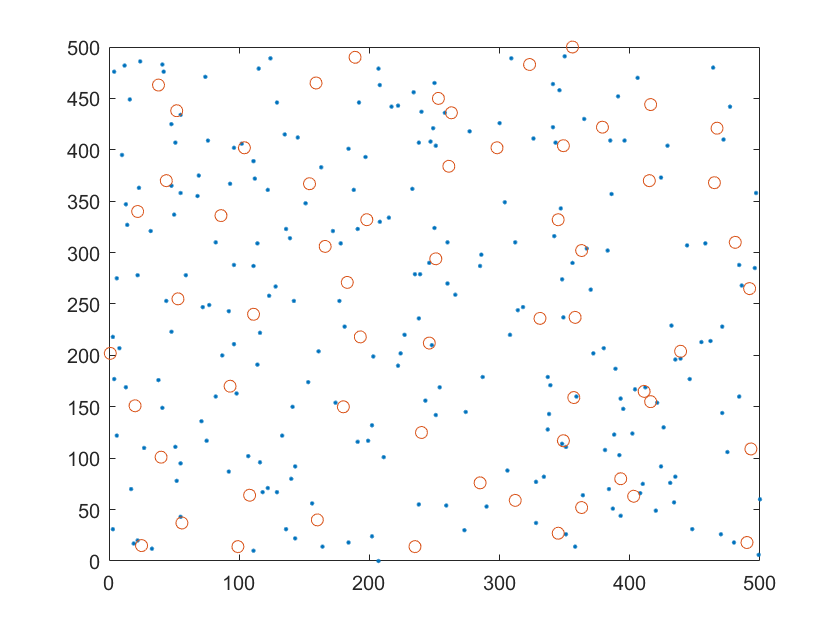

Cannot find an exact (case-sensitive) match for 'Tabusearch'

The closest match is: TabuSearch in C:\Users\Henri\Documents\Informatik\Sistemas Intelligentes\Git\Practica Global\TabuSearch.m

CMax = 4500;
Nveces = 1000;
N = 300;
M = 60;
Max_Iterations = 1000;

bestCostTotal_Annealing = Inf;
bestCostTotal_Tabu = Inf;
bestCostTotal_Generative = Inf;

sumCostes_Annealing=0;
sumCostes_Tabu=0;
sumCostes_Generative=0;

sumIterations_Annealing = 0;
sumIterations_Tabu = 0;
sumIterations_Generative = 0;

sumtime_Annealing=0;
sumtime_Tabu=0;
sumtime_Generative=0;
for i = 1:Nveces
    %Random Coordinates of possible Satelite Positions
    stations = randi([0 500],300,2);
    
    %Random selected Installation Costs for possible Positions
    sCost = randi([10,100],300,1);
    
    %Random selected Positions as Representatives
    satelites = randperm(300)';
    satelites = satelites(1:60);
    
    displaySatelites(stations,satelites);
    
    %Annealing Search
    tic
    [bestCost_Annealing, iterations_Annealing, SolutionAnnealing] = AnnealingSearch(stations,sCost,satelites,CMax,M);
    time_Annealing = toc;
    sumtime_Annealing = sumtime_Annealing + time_Annealing;
    sumCostes_Annealing = sumCostes_Annealing + bestCost_Annealing
    sumIterations_Annealing = sumIterations_Annealing + iterations_Annealing;
    if(bestCostTotal_Annealing>bestCost_Annealing)
        bestCostTotal_Annealing = bestCost_Annealing;
    end
    displaySatelites(stations,SolutionAnnealing);
    
    %Tabu Search
    tic
    [bestCost_Tabu, iterations_Tabu] = TabuSearch(20, Max_Iterations,stations, sCost, satelites);
    time_Tabu = toc;
    sumtime_Tabu = sumtime_Tabu + time_Tabu;
    sumCostes_Tabu = sumCostes_Tabu + bestCost_Tabu
    sumIterations_Tabu = sumIterations_Tabu + iterations_Tabu;
    if(bestCostTotal_Tabu>bestCost_Tabu)
        bestCostTotal_Tabu = bestCost_Tabu;
    end
    
    
    %Generative Search
    tic
    [instalation_Cost, bestCost_Generative, iterations_Generative, SolutionGenerative] = GeneticSearch(N,M,stations,sCost);
    time_Generative = toc;
    sumtime_Generative = sumtime_Generative + time_Generative;
    sumCostes_Generative = sumCostes_Generative + bestCost_Generative;
    sumIterations_Generative = sumIterations_Generative + iterations_Generative;
    if(bestCostTotal_Generative>bestCost_Generative)
        bestCostTotal_Generative = bestCost_Generative;
    end  
end

Now we calculate the means and show our data in a table

meanIterations_Annealing = (sumIterations_Annealing/Nveces);
meanIterations_Tabu = (sumIterations_Tabu/Nveces);
meanIterations_Generative = (sumIterations_Generative/Nveces);
meanTime_Annealing = (sumtime_Annealing/Nveces);
meanTime_Tabu = (sumtime_Tabu/Nveces);
meanTime_Generative = (sumtime_Generative/Nveces);
meanCoste_Annealing = (sumCostes_Annealing/Nveces);
meanCoste_Tabu = (sumCostes_Annealing/Nveces);
meanCoste_Generative = (sumCostes_Annealing/Nveces);

Annealing = [meanCostes_Annealing; meanTime_Annealing; meanIterations_Annealing; bestCostTotal_Annealing];
Tabu = [meanCostes_Tabu; meanTime_Tabu; meanIterations_Tabu; bestCostTotal_Annealing];
Generative = [meanCostes_Generative; meanTime_Generative; meanIterations_Generative; bestCostTotal_Generative];
T = table(Annealing, Tabu, Generative,'RowNames', {'Cost (Mean)'; 'Time (Mean)'; 'Iterations (Mean)'; 'best cost overall'});
T